# Numerical Methods for Optimization and Control Theory

## Daniel Kuknyo - Assignment 2

Assigned tasks: 1, 5, 10, 12

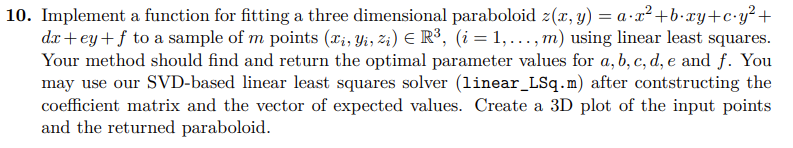

## Generating the space

The points are sampled from a normal distribution in order to have a nicer look. 

clear all; clc;

% Linear Space boundaries
x_min =  1;
x_max = -4;
y_min =  2;
y_max = -2; 
z_min =  0;
z_max = 50;
bounds = [x_min x_max y_min y_max z_min z_max];

% Genearate the linear space
res = 1000;
X = linspace(x_min, x_max, res);
Y = linspace(y_min, y_max, res);
space = meshgrid(X,Y);
[X_m, Y_m] = meshgrid(X,Y);

## Creating the expected values

% Number of points to generate
m = 1000;
f_params = [10;20;30;30;40;30]; % Parameters of the generative function

% Function for the equation of a parabola
f = @(x, y, a, b, c, d, e, f) a*x^2 + b*x*y + c*y^2 + d*x + e*y + f

f = function_handle with value:
    @(x,y,a,b,c,d,e,f)a*x^2+b*x*y+c*y^2+d*x+e*y+f


% Vector of expected values
y = generate_points(m, f, f_params, X_m, Y_m, res)

y =    -0.1562   -0.6316    0.9600   -0.7417   -2.9540   -1.7778   -2.0280   -3.2993   -3.3694   -2.5986   -0.7768   -2.1782   -2.3133   -2.9640    0.5796    0.1892   -0.7067   -1.1371   -1.0470   -2.7788    0.9800    0.5195   -1.2823   -0.8519   -3.3794   -0.4965   -2.1381   -3.5646   -2.4084   -0.1311   -3.1942   -3.3043    0.3343   -0.3964   -3.5145   -0.2913   -2.0781    0.3594   -1.5275    0.7147    0.6897    0.8899   -3.8348   -0.3113   -1.4575   -0.9770   -2.2933   -3.4294   -1.6727    0.0941
    2.0000    2.0000    1.9960    1.9920    1.9920    1.9880    1.9880    1.9880    1.9880    1.9840    1.9720    1.9720    1.9720    1.9720    1.9640    1.9600    1.9560    1.9560    1.9520    1.9520    1.9479    1.9439    1.9439    1.9359    1.9239    1.9159    1.9119    1.9079    1.9039    1.8959    1.8959    1.8959    1.8879    1.8879    1.8879    1.8839    1.8719    1.8679    1.8679    1.8639    1.8639    1.8599    1.8559    1.8519    1.8398    1.8198    1.8198    1.8198    1.8158    1

## Assemble the coefficient matrix

% Assemble J matrix
J = [];
for i = 1:m
    nx = y(1, i);
    ny = y(2, i);
    vec = [nx^2 nx*ny ny^2 nx ny 1];
    J = [J; vec];
end

## Find the optimal parabola coefficients

The original parameters of the generator function and the estimated parameters are also visible

n_coeffs = size(J,2);
y_next = y(3,:)';

% Estimate the parameters
x = linear_svd(J, y_next, n_coeffs);

% Display the true/estimated params
[f_params'; x']

ans =    10.0000   20.0000   30.0000   30.0000   40.0000   30.0000
    9.7795   19.5486   30.0366   28.6855   38.9806   29.2112


## Plot the results

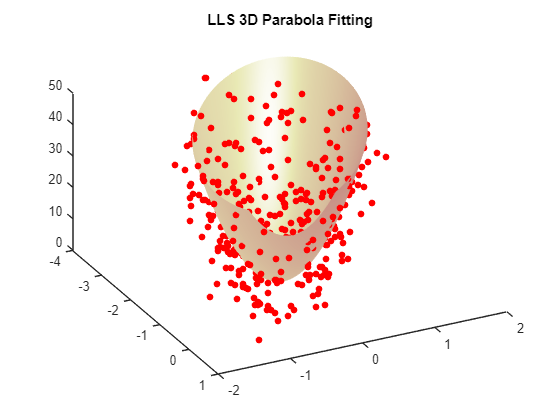

% Create the points for the parabola
Z = zeros(res,res);
for i = 1:res
    for j = 1:res
        Z(i,j) = f(X_m(i,j), Y_m(i,j), x(1), x(2), x(3), x(4), x(5), x(6));
    end
end

figure; 
hold on;

% Plot the parabola
surfl(X_m,Y_m,Z);

% Plot the points
for i = 1:size(y,2)
    plot3(y(1,i), y(2,i), y(3,i), '.', ...
        'MarkerSize', 15, ...
        'MarkerEdgeColor', 'red', ...
        'MarkerFaceColor', [1 .6 .6]);
end

view([63.30 41.40])
zlim([z_min z_max]) % Remove this one to see the whole function - it was added for aesthetics
title("LLS 3D Parabola Fitting");
colormap("pink");
shading interp;
hold off;

## Functions

function pts = generate_points(m, f, x, X_m, Y_m, res)
    % Create the Z coordinates according to f function
    Z = zeros(res,res);
    for i = 1:res
        for j = 1:res
            Z(i,j) = f(X_m(i,j), Y_m(i,j), x(1), x(2), x(3), x(4), x(5), x(6)); 
        end
    end

    % Add deviance
    noise_lvl = 15;
    Z = Z + noise_lvl * randn(1,res);

    % Flatten and assemble into 3*res^2 matrix
    x_coords = reshape(X_m.', 1, []);
    y_coords = reshape(Y_m.', 1, []);
    z_coords = reshape(Z.', 1, []);
    
    % Assemble into a single 3*m matrix
    coords = [x_coords; y_coords; z_coords];

    % Subsample the matrix to contain m points
    all_inds = 1:size(coords, 2);
    indices = sort(randsample(all_inds, min(m, size(coords,2))));
    pts = coords(:, indices);
end

function x = linear_svd(J, y, n)
    % Compute the SVD:
    [U,S,V] = svd(J);
    s = diag(S);
    
    % Determine the effective rank r of A using singular values
    r = 1;
    while(r < size(J,2) & s(r+1) >= max(size(J)) * eps * s(1))
        r = r + 1;
    end
    
    d = U' * y;
    x = V * ([d(1:r)./s(1:r); zeros(n-r,1)]);    
end
